%ode是求微分方程的数值解（即返回原函数的各点坐标）

% y'=-2y+2x^2+2x ,0<=x<=0.5,y(0)=1
xy = @(x,y)-2*y+2*x^2+2*x;
[x,y] = ode45(xy,[0,0.5],1);

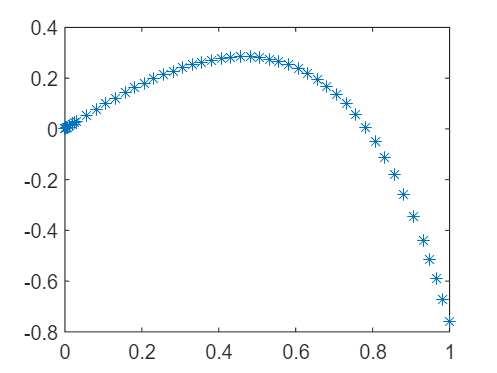

% y'''-3y''-y'y=0,y(0)=0,y'(0)=1,y''(0)=-1
%高阶微分方程要做变量代换化成一阶
%设y1=y,y2=y',y3=y''
dy = @(t,y)[y(2);y(3);3*y(3)+y(2)*y(1)];
[tt,yy]=ode45(dy,[0,1],[0;1;-1]);
plot(tt,yy(:,1),'*')

bv